## **Test 1:**

### **f_s = 32 kHz:**

fs = 32000;

#### **L = 16:**

    0.0015



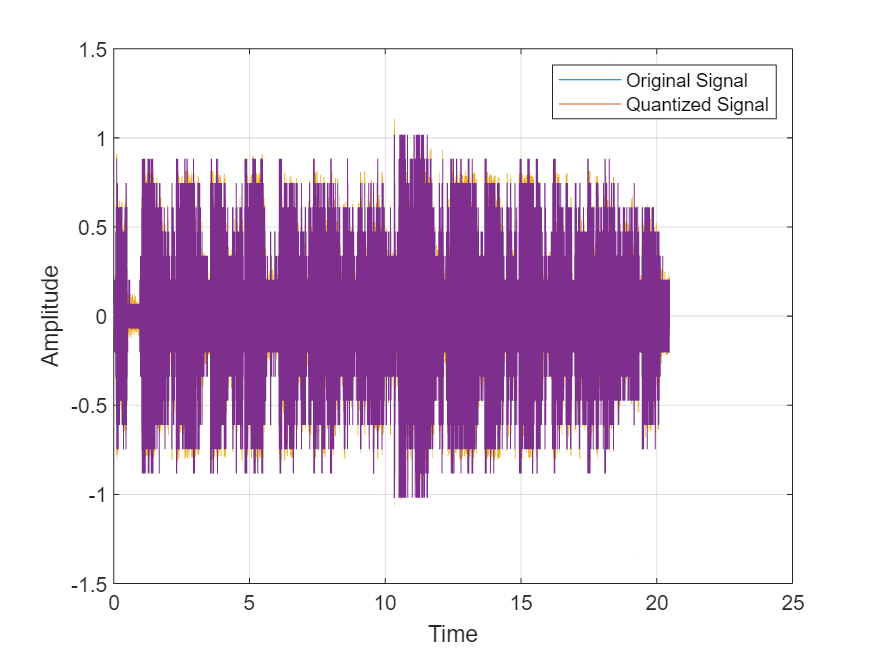

L = 16;
[x,t] = mySampling("ana_qader.mp3",fs);
[tt, xx] = Quantizer("Mid-rise", t, x, L, (max(x)-min(x))/2);

levels = generateLevels("Mid-rise", L,  (max(x)-min(x))/2);
[binaryMap, ~] = generateBinaryMap(levels);
[encoded_msg_time, encoded_msg] = Encoder(tt, xx, "Manchester Signaling", binaryMap, L)

Error using indexing
The specified key is not present in this container.

Error in Encoder (line 13)
    binaryEncoding(i) = binary_map(quantized_signal_time_vector(i))

#### **L = 64:**

L = 64;

#### **L = 256:**

L = 256;

### **f_s = 16 kHz:**

fs = 16;

#### **L = 16:**

L = 16;

#### **L = 64:**

L = 64;

#### **L = 256:**

L = 256;

### **f_s = 4 kHz:**

fs = 4;

#### **L = 16:**

L = 16;

#### **L = 64:**

L = 64;

#### **L = 256:**

L = 256;

## Test 2: